# ECE 2409

#### Fall 2020

#### Theo Andonyadis

#### Homework 4

clc;clear;close all
c=datetime;
fprintf('Last run was %s\n',c)

Last run was 16-Oct-2020 11:27:10


# a)

x=-7:0.1:7;
y1=x.^2-2;
y2=2.*x+1;
plot(x,y1,'r','LineWidth',2)
hold on
plot(x,y2,'b','LineWidth',2);

# b)

captiony1 = sprintf('y = x^2-2');
text(-6.5, 7, captiony1, 'FontSize', 16, 'Color', 'r');
captiony2 = sprintf('y = 2*x+1');
text(3.5, 6, captiony2, 'FontSize', 16, 'Color', 'b');

# c)

ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

# d)

grid on
axis('square')

# e)

ylim([-5 9])
xlim([-7 7])
set(gca,'xtick',[-7:1:7],'ytick',[-9:1:9])
set(findobj(gcf,'type','axes'),'FontSize',12,'FontWeight','Bold', 'LineWidth', 2);
box off;

# f)

d=abs(y1-y2);
[val idx]=sort(d);
xintercept1=x(idx(1));
yintercept1=2*xintercept1+1;
xintercept2=x(idx(2));
yintercept2=xintercept2^2-2;
hold on

# g)

plot(xintercept1,yintercept1,'k*','LineWidth',8)
plot(xintercept2,yintercept2,'k*','LineWidth',8)

# h)

intlabel1=sprintf('(%i, %i)',xintercept1,yintercept1);
text(-4.1, -1.5, intlabel1, 'FontSize', 16, 'Color', 'k');
intlabel2=sprintf('(%i, %i)',xintercept2,yintercept2);
text(3.4, 7, intlabel2, 'FontSize', 16, 'Color', 'k');

# i)

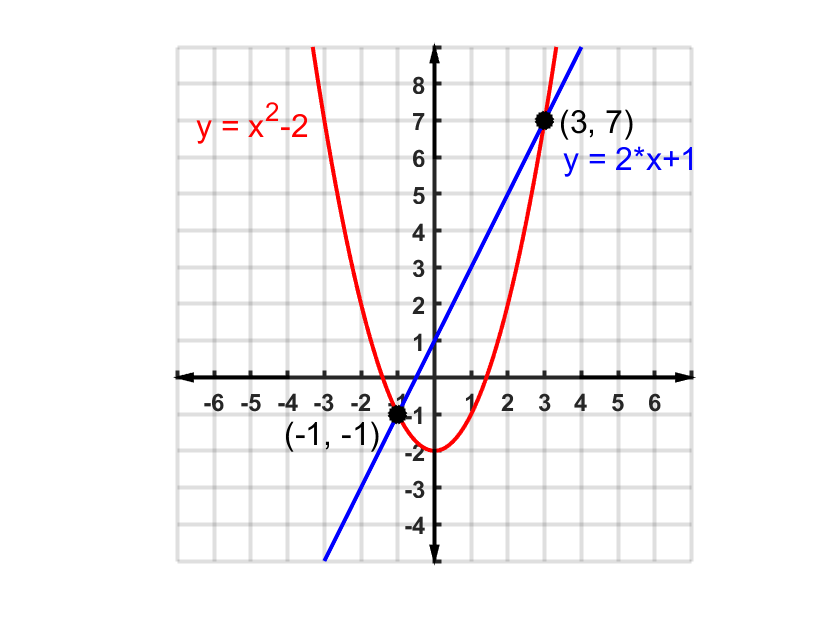

h1=arrows(-4,0,2.9,270,[0.05,0.1,0.1,0],'FaceColor','k','LineWidth',2);
h2=arrows(4,0,2.9,90,[0.05,0.1,0.1,0],'FaceColor','k','LineWidth',2);
h3=arrows(0,6,2.9,0,[0.05,0.1,0.1,0],'FaceColor','k','LineWidth',2);
h4=arrows(0,-2,2.9,180,[0.05,0.1,0.1,0],'FaceColor','k','LineWidth',2);